data = WeatherData()
data.plotVariable(VariableType.TEMPERATURE)

x = linspace(0,7,100);
y = linspace(0,7,100);

[xMesh,yMesh] = meshgrid(x,y);
[n,m] = size(xMesh);
X = [];
z = [];
%Probemos la función implementada con datos para z = 2*x + 3*y +7 con ruido
%agregado
for i = 1:n
    for j=1:m
        X = [X,[xMesh(i,j);yMesh(i,j)]];
        z = [z,[2*xMesh(i,j)+3*yMesh(i,j)+7]];        
    end
end

z = awgn(z,50,'measured');
Y = z;
dataCooker = DataPrecook();
[trainingSet, trainingSetResults, validationSet, validationSetResults] = dataCooker.splitData(X,Y,0.2);



fitter = LinearModelFitter();
[modelParams, rSquared, MSE] = fitter.fitByLeastSquares(trainingSet, trainingSetResults, validationSet,  validationSetResults);
disp(string(modelParams));

    "6.9966"    "2.0006"    "3.0004"



disp("R^2 "+string(rSquared));

R^2 0.99984


disp(MSE)

    0.0063



%Ahora intentemos hacer lo mismo pero con descenso del gradiente
x = linspace(0,7,100);
y = linspace(0,7,100);

[xMesh,yMesh] = meshgrid(x,y);
[meshHeight,meshWidth] = size(xMesh);
X = [];
z = [];
%Probemos la función implementada con datos para z = 2*x + 3*y +7 con ruido
%agregado
for i = 1:meshHeight
    for j=1:meshWidth
        X = [X,[xMesh(i,j);yMesh(i,j)]];
        z = [z,[2*xMesh(i,j)+3*yMesh(i,j)+7]];        
    end
end

z = awgn(z,50,'measured');
Y = z;

dataCooker = DataPrecook();
[trainingSet, trainingSetResults, validationSet, validationSetResults] = dataCooker.splitData(X,Y,0.2);


epochs = 2000;
learningRate = 0.02;
fitter = LinearModelFitter();
[beta, performanceTraining, performanceValidation, rSquared] = fitter.fitByGradientDescent(epochs, learningRate, trainingSet, trainingSetResults, validationSet, validationSetResults);

disp(string(beta));

    "6.998"    "2.0009"    "3.0001"



disp("R^2 "+string(rSquared));

R^2 0.99984


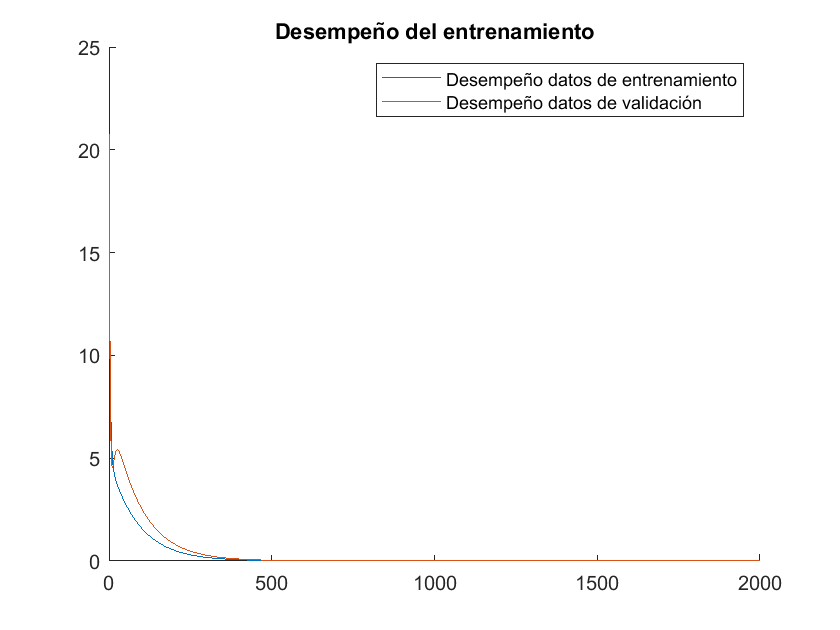


epochArray = 1:epochs;
figure()
hold on 
title("Desempeño del entrenamiento")
plot(epochArray, performanceTraining)
plot(epochArray, performanceValidation)
hold off
legend('Desempeño datos de entrenamiento','Desempeño datos de validación')